im0 = imread('08_2/2.jpg');
imp0 = imread('08_2/ppt.jpg');
imgray = rgb2gray(im0);

## Edge Detection

Using Sobel Operator we can take the derivative of the image.

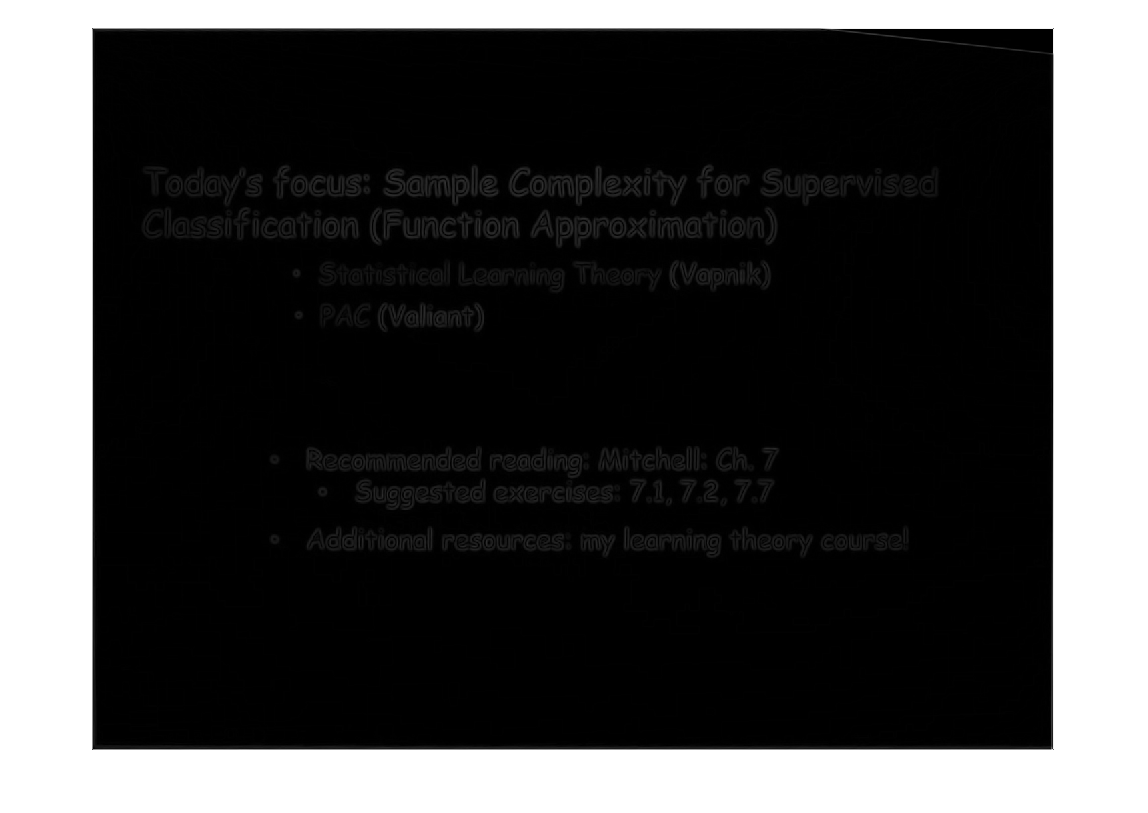

dx = conv2([-1 0 1; -2 0 2; -1 0 1], imgray);
dy = conv2([-1 -2 -1; 0 0 0; 1 2 1], imgray);
gradient = sqrt((dx.*dx) + (dy.*dy));
max_val = max(max(gradient));
min_val = min(min(gradient));
norm_gradient = uint8(round(255*(gradient-min_val)/(max_val-min_val)));
imshow(norm_gradient);

colsum = sum(double(norm_gradient));
rowsum = sum(double(norm_gradient), 2);
[val1 ,idx1] = max(colsum(4:698));
fprintf("First column: %f with value %f", idx1, val1);

First column: 1.000000 with value 14362.000000

[val2 ,idx2] = max(colsum(699:1394));
fprintf("Second column: %f with value %f", idx2+699, val2);

Second column: 733.000000 with value 6091.000000

[val3 ,idx3] = max(rowsum(4:540));
fprintf("First row: %f with value %f", idx3, val3);

First row: 1.000000 with value 37025.000000

[val4 ,idx4] = max(rowsum(540:1076));
fprintf("Second row: %f with value %f", idx4+540, val4);

Second row: 768.000000 with value 17440.000000

    "Image NOT cropped"



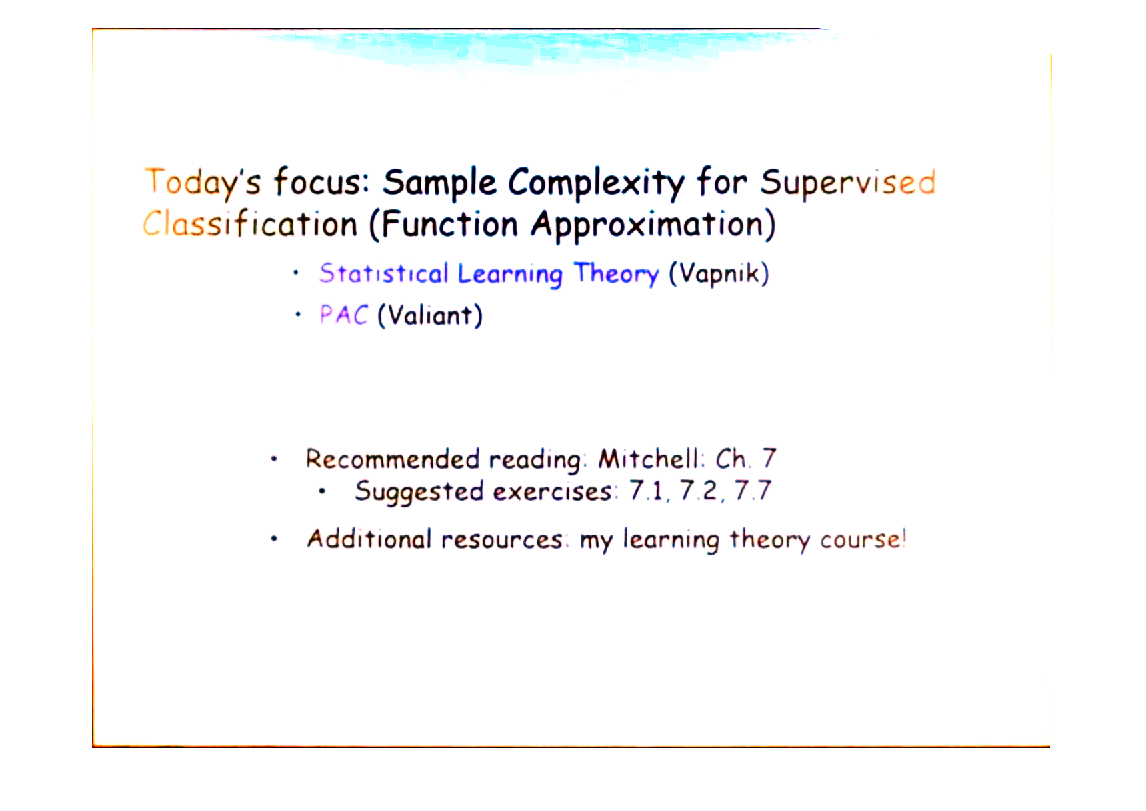

if val1+val2+val3+val4 < 100000
    display("Image NOT cropped")
    imshow(im0)
    imshow(imhistmatch(im0, imp0))
else
    display("Image cropped")
    imshow(imcrop(im0, [idx1 idx3 idx2-idx1+699 idx4-idx3+540]));
    imshow(imhistmatch(imcrop(im0, [idx1 idx3 idx2-idx1+699 idx4-idx3+540]), imp0));
end